# Regression - TSK Models

## Problem Description

In this project, we are tasked with implementing TSK (Takagi-Sugeno-Kang) fuzzy systems, solving regression problems. 

This project is two fold. First we are given a simple dataset called '*Airfoil Self-Noise dataset*'. We then will be training 4 specific models with different configurations and evaluating their performance.

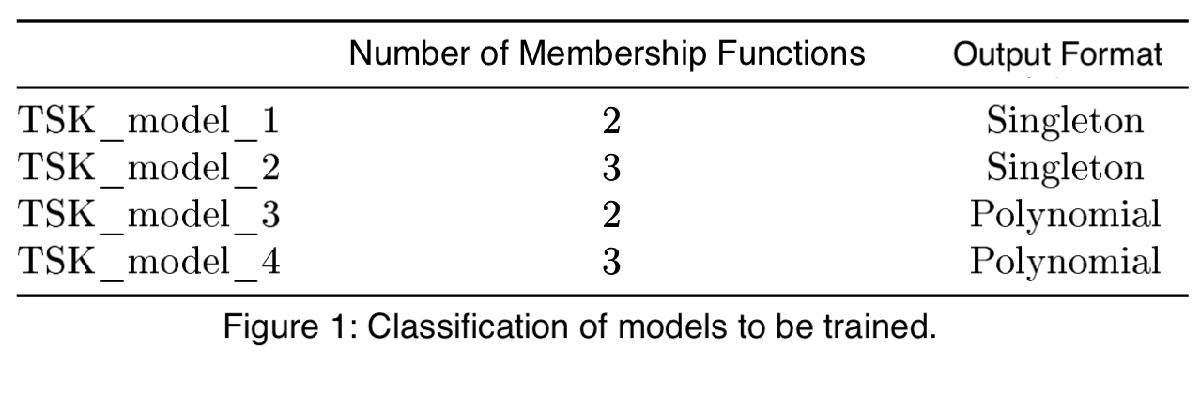

Fig. 1 Models to be trained

The second part, includes a more complex, high-dimensional dataset '*Superconductivity dataset*'. Given its nature, before implementing any model, we are required to reduce its dimensions and fuzzy set of rules. We will then train the model, and assess its performance. 

For both implementations, we will split the datasets in a 60-20-20 ratio for training-validating-checking. Each model's performace, learning curve and prediction errors will be visualised and analyzed.

## TSK Application on Simple Dataset

### Airfoil Self-Noise Dataset Overview

In this section, we will concentrate on the '*Airfoil Self-Noise dataset*', which comprises of 1503 data points, with 5 features and 1 output each.

Specifically the data points have the following features:

Input:

- f: Frequency $\left\lbrack \mathrm{Hz}\right\rbrack$

- alpha: Angle of attack $\left\lbrack \degree \right\rbrack$

- c: Chord length $\left\lbrack m\right\rbrack$

- U_infinity: Free-stream velocity$\left\lbrack \frac{m}{s}\right\rbrack$

- delta: Suction side displacement thickness $\left\lbrack m\right\rbrack$

Output:

- SSPL: Scaled sound pressure level $\left\lbrack \textrm{dB}\right\rbrack$

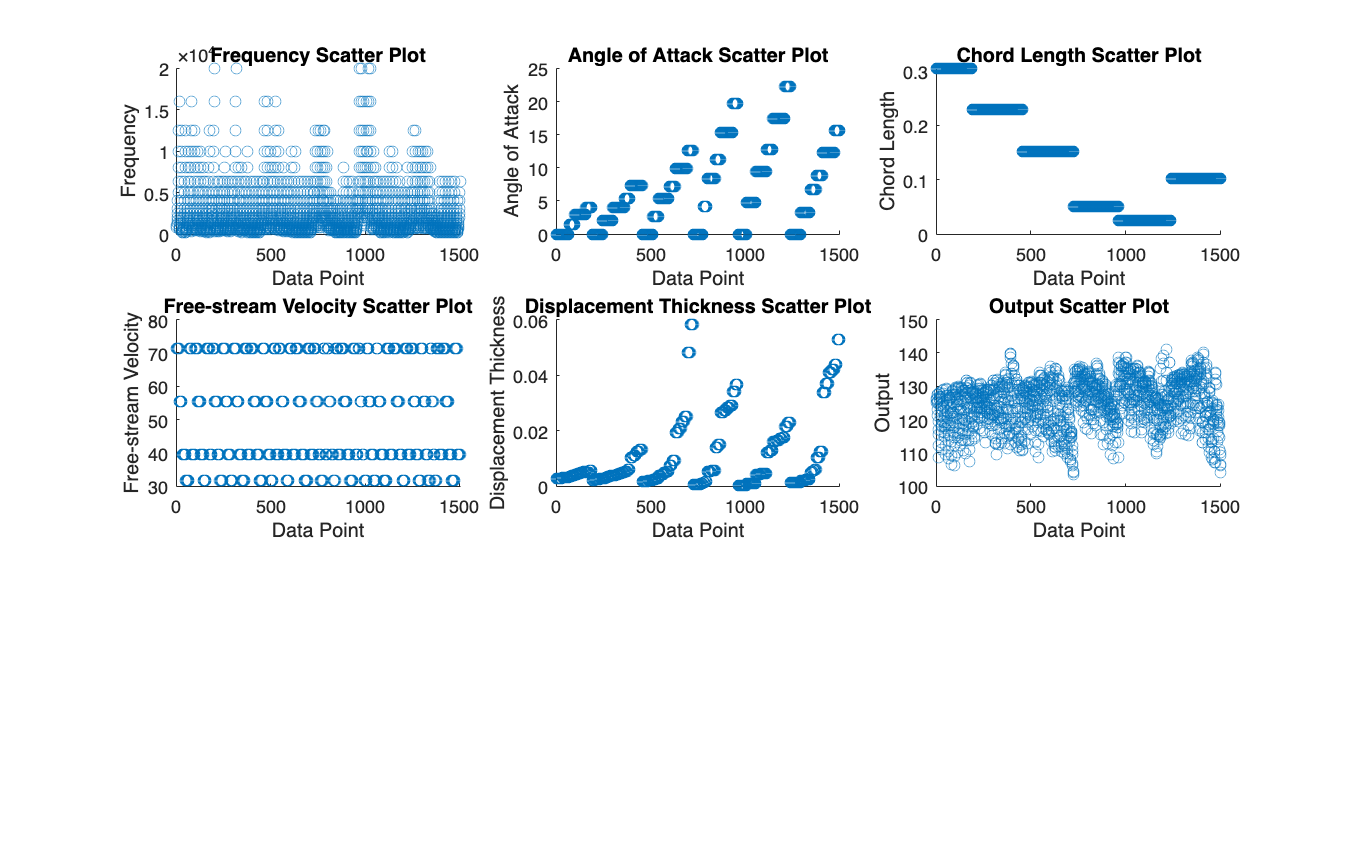

clc; clearvars; close all;
warning('off','all')
addpath("lib")
addpath("lib/datasets")
data_1 = table2array(readtable("datasets/airfoil_self_noise.dat"));

% Visualize Data
feature_names_1 = {'Frequency', 'Angle of Attack', 'Chord Length', 'Free-stream Velocity', 'Displacement Thickness'};
visualize_data(data_1, feature_names_1, 1:5);

[Dtrn_1, Dval_1, Dchk_1] = split_data(data_1);

Dimensions of Training Data:
   902     6

Dimensions of Validation Data:
   300     6

Dimensions of Checking Data:
   301     6



### TSK Model 1

We will begin with implementing the first model, according the the requirements.

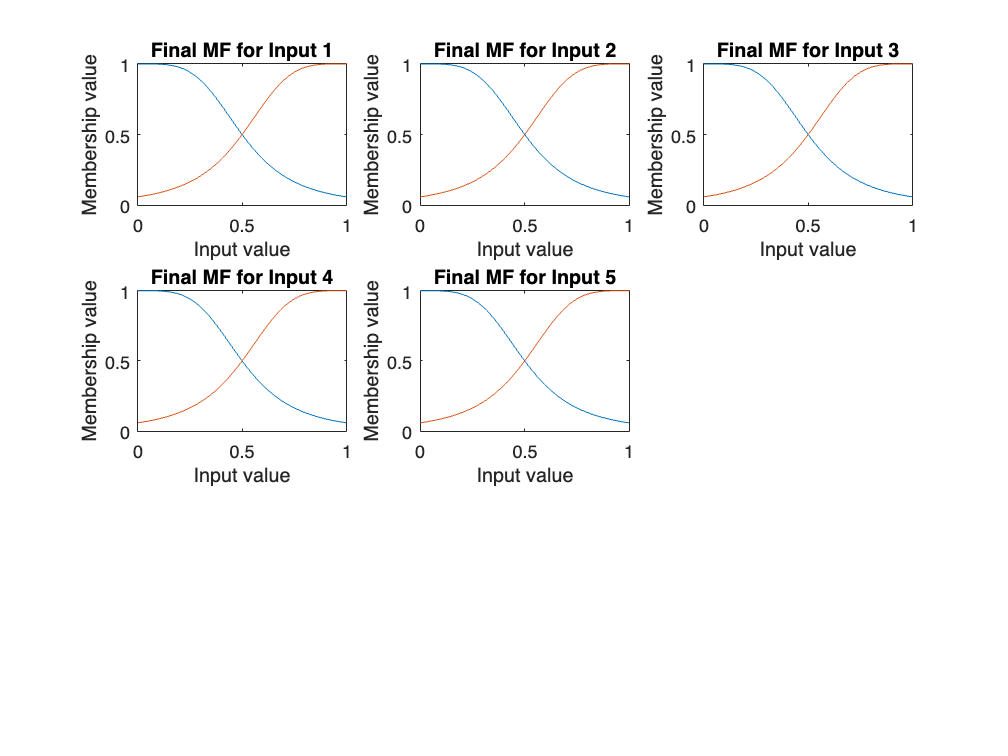

% Define configuration for Model 1
model_1 = struct('Part', '1','NumMFs', 2, 'InputMFT', 'gbellmf', 'OutputMFT', 'constant');

% Initialize Model 1
initial_fis_1 = initialize_tsk_model(Dtrn_1, model_1);
plot_mf(initial_fis_1, 5);

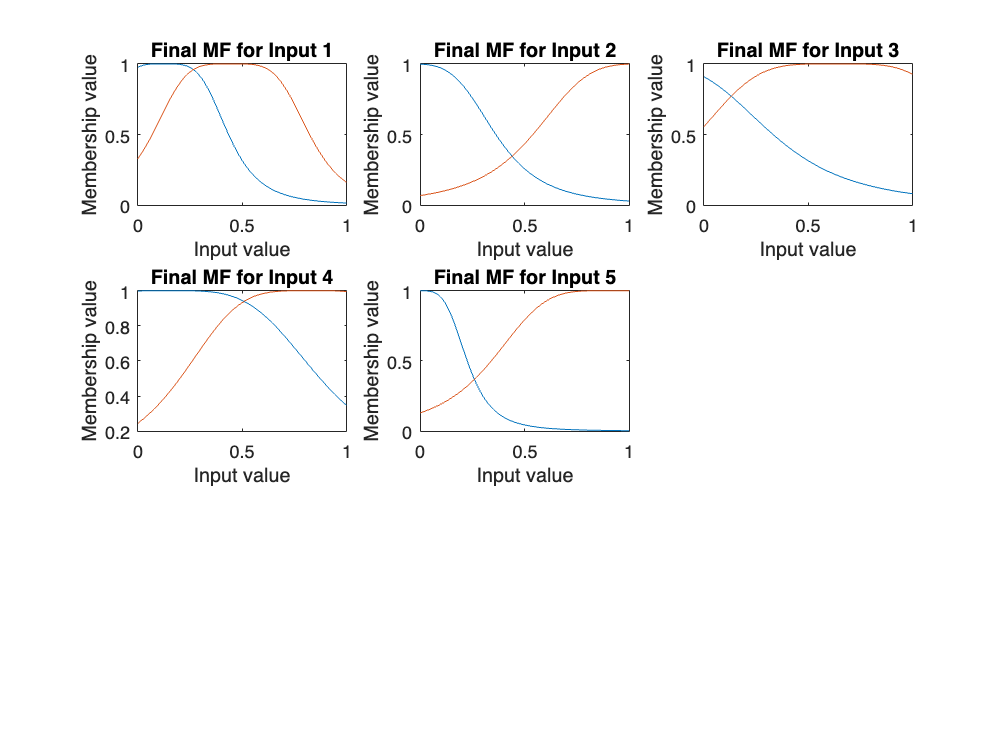

% Train Model 1
tic;
[trained_fis_1, training_info_1] = train_tsk_model(initial_fis_1, Dtrn_1, Dval_1, 100);
time_1 = toc;
plot_mf(trained_fis_1, 5);

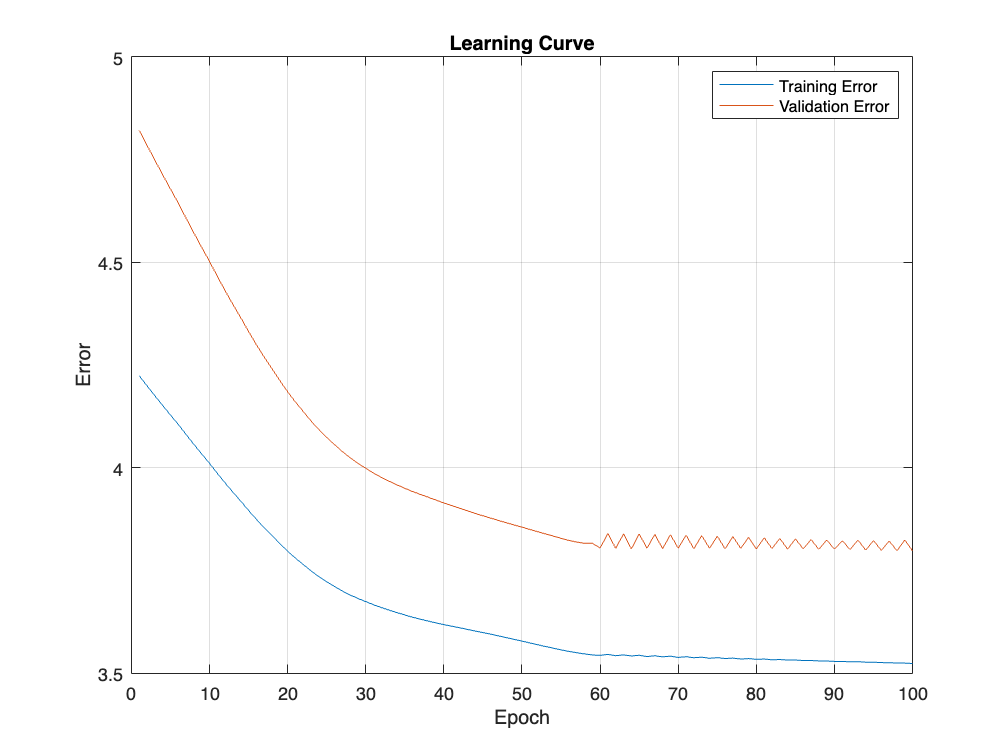

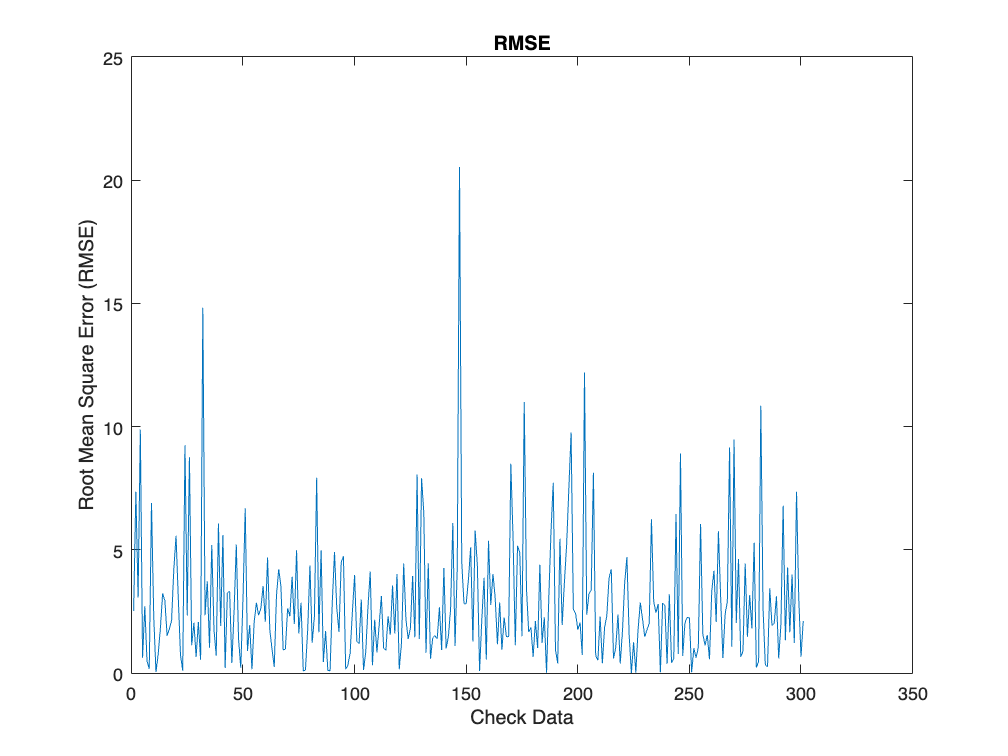

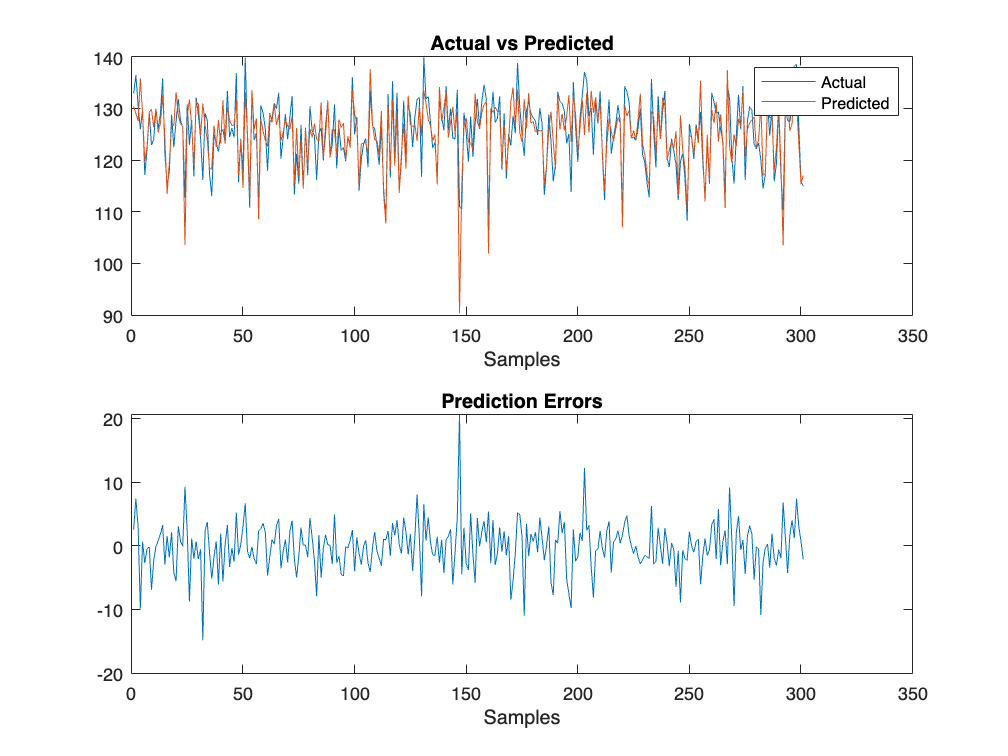

% Evaluate Model 1
[Rmse1, Nmse1, Ndei1, R21] = metrics_evaluation(trained_fis_1, Dchk_1);
plot_metrics(Dchk_1(:, end), evalfis(trained_fis_1, Dchk_1(:, 1:end-1)), training_info_1.trainError, training_info_1.chkError);

model_1_metrics = [Rmse1; Nmse1; Ndei1; R21];
fprintf('Error metrics for TSK model:\n RMSE: %.4f, NMSE: %.4f, NDEI: %.4f, R2: %.4f\n', Rmse1, Nmse1, Ndei1, R21);

Error metrics for TSK model:
 RMSE: 3.8397, NMSE: 0.3379, NDEI: 0.5813, R2: 0.6621


### TSK Model 2

Based on the implementation of the first, we will continue with the second model.

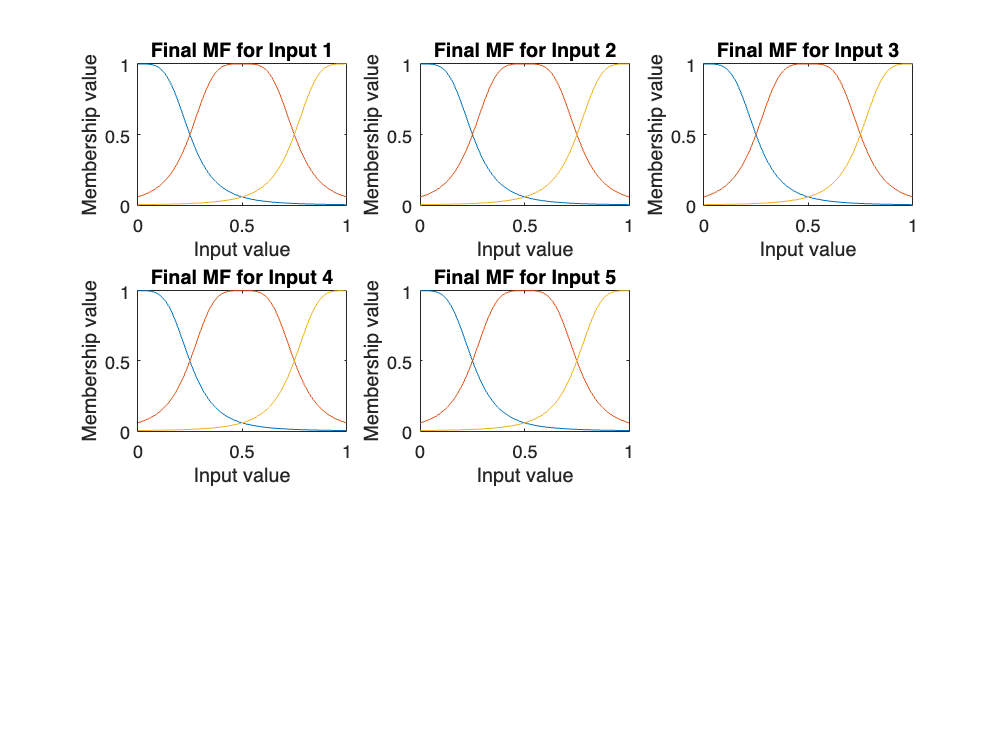

% Define configuration for Model 2
model_2 = struct('Part', '1','NumMFs', 3, 'InputMFT', 'gbellmf', 'OutputMFT', 'constant');

% Initialize Model 2
initial_fis_2 = initialize_tsk_model(Dtrn_1, model_2);
plot_mf(initial_fis_2, 5);

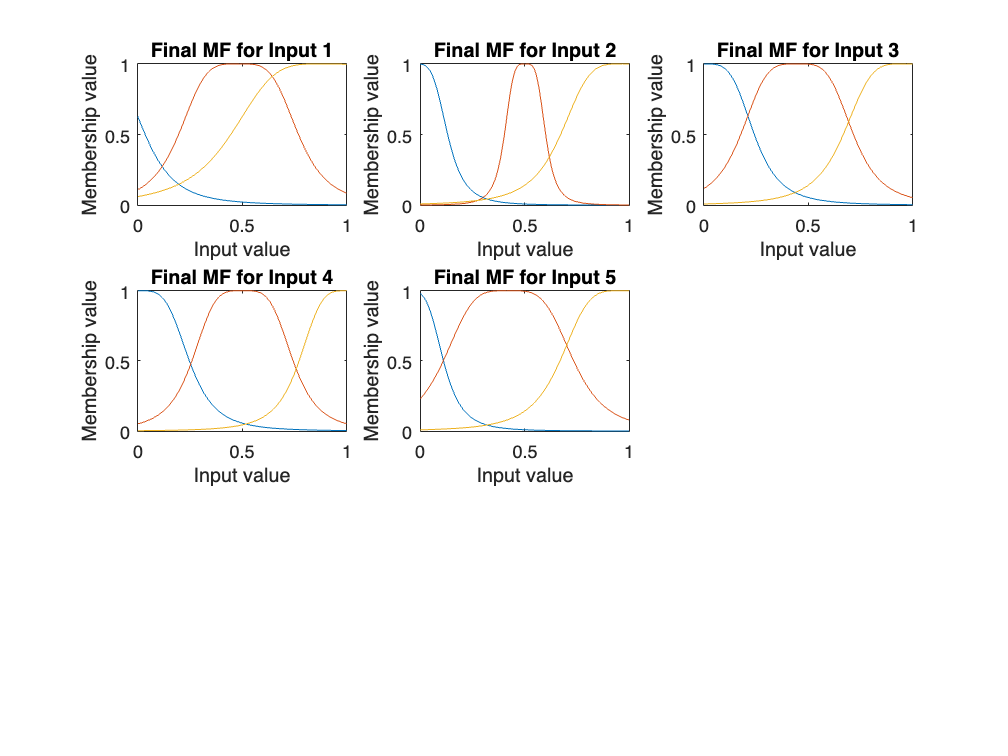

% Train Model 2
tic;
[trained_fis_2, training_info_2] = train_tsk_model(initial_fis_2, Dtrn_1, Dval_1, 100);
time_2 = toc;
plot_mf(trained_fis_2, 5);

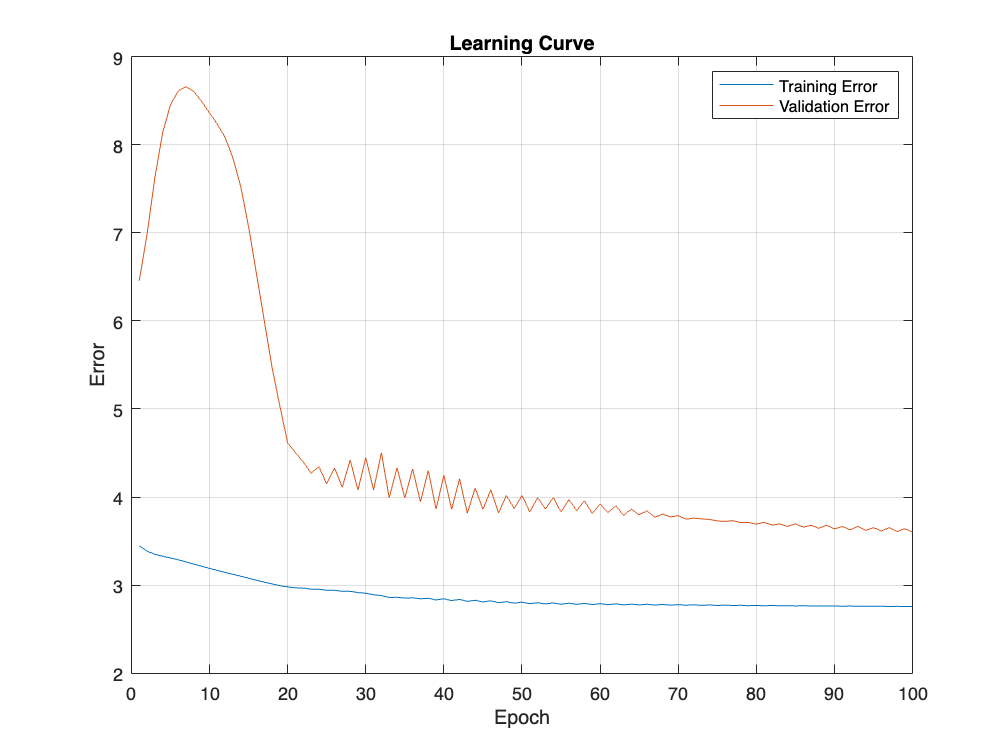

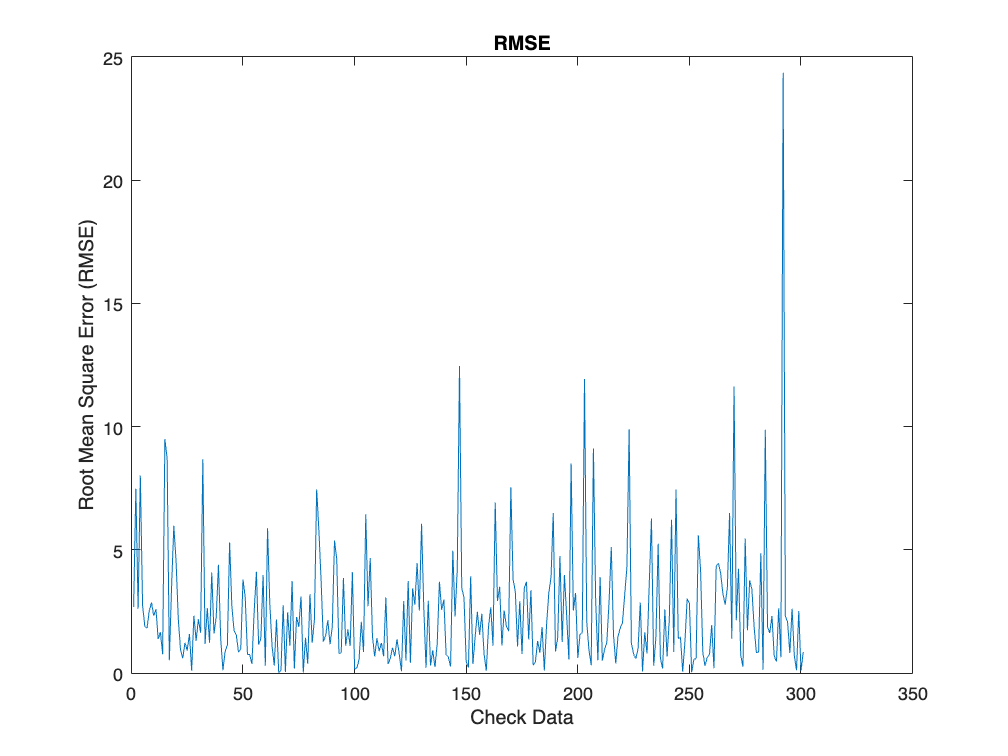

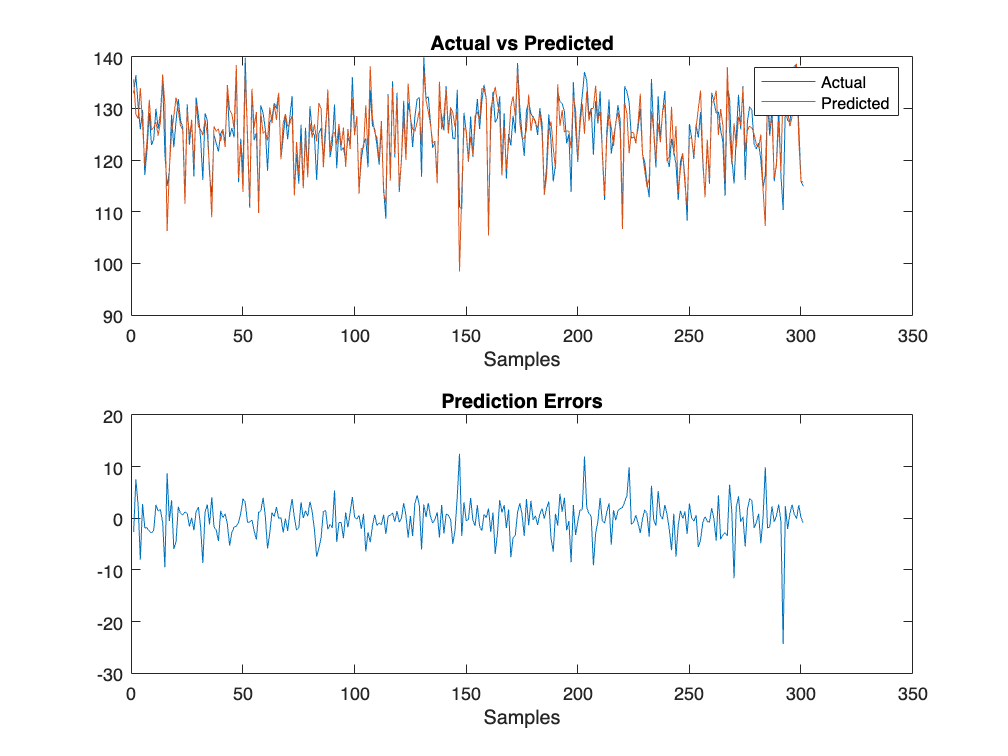

% Evaluate Model 2
[Rmse2, Nmse2, Ndei2, R22] = metrics_evaluation(trained_fis_2, Dchk_1);
plot_metrics(Dchk_1(:, end), evalfis(trained_fis_2, Dchk_1(:, 1:end-1)), training_info_2.trainError, training_info_2.chkError);

model_2_metrics = [Rmse2; Nmse2; Ndei2; R22];
fprintf('Error metrics for TSK model 2:\n RMSE: %.4f, NMSE: %.4f, NDEI: %.4f, R2: %.4f\n', Rmse2, Nmse2, Ndei2, R22);

Error metrics for TSK model 2:
 RMSE: 3.5464, NMSE: 0.2882, NDEI: 0.5369, R2: 0.7118


### TSK Model 3

Similarly, we continue with the third model, according the the required configuration.

% Define configuration for Model 3
model_3 = struct('Part', '1','NumMFs', 2, 'InputMFT', 'gbellmf', 'OutputMFT', 'linear');

% Initialize Model 3
initial_fis_3 = initialize_tsk_model(Dtrn_1, model_3);
plot_mf(initial_fis_3, 5);

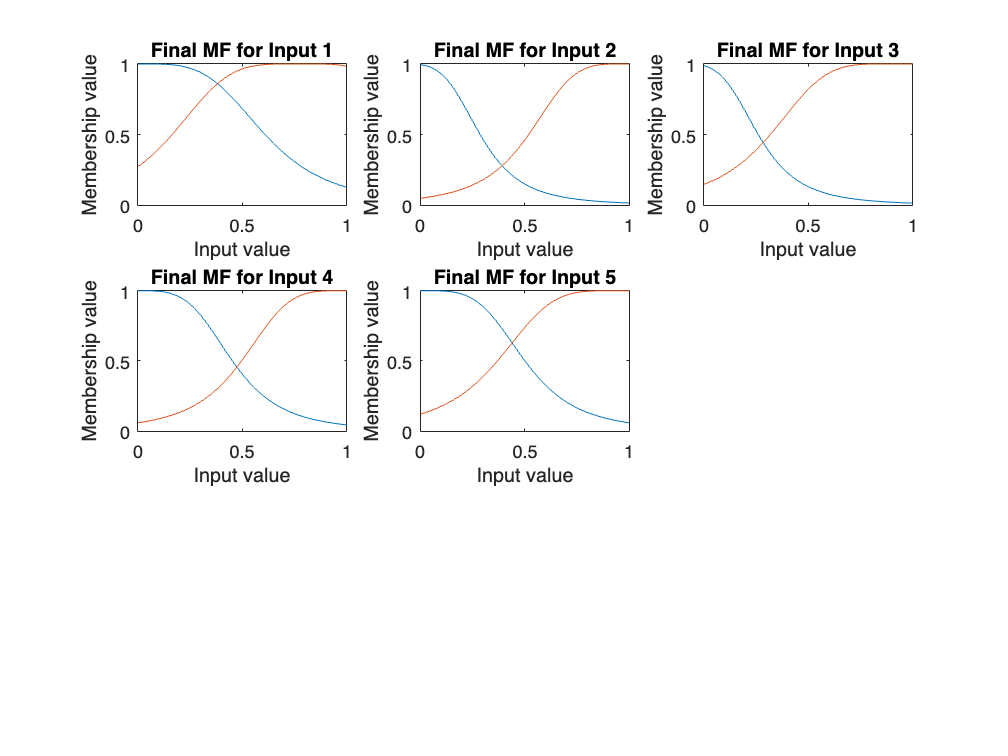

% Train Model 3
tic;
[trained_fis_3, training_info_3] = train_tsk_model(initial_fis_3, Dtrn_1, Dval_1, 100);
time_3 = toc;
plot_mf(trained_fis_3, 5);

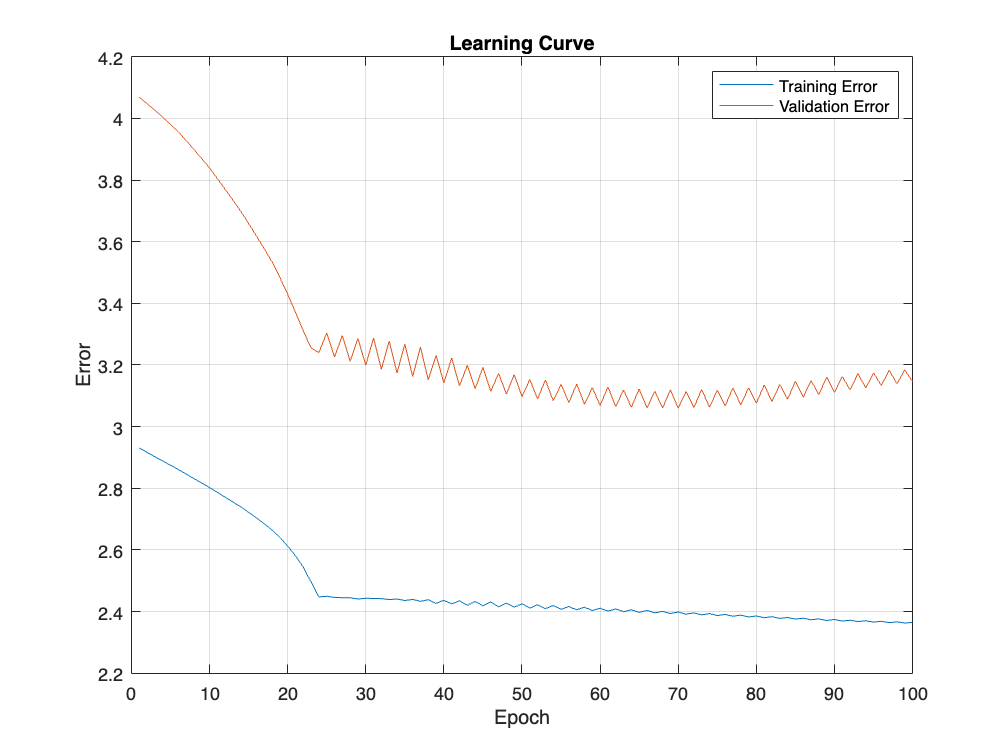

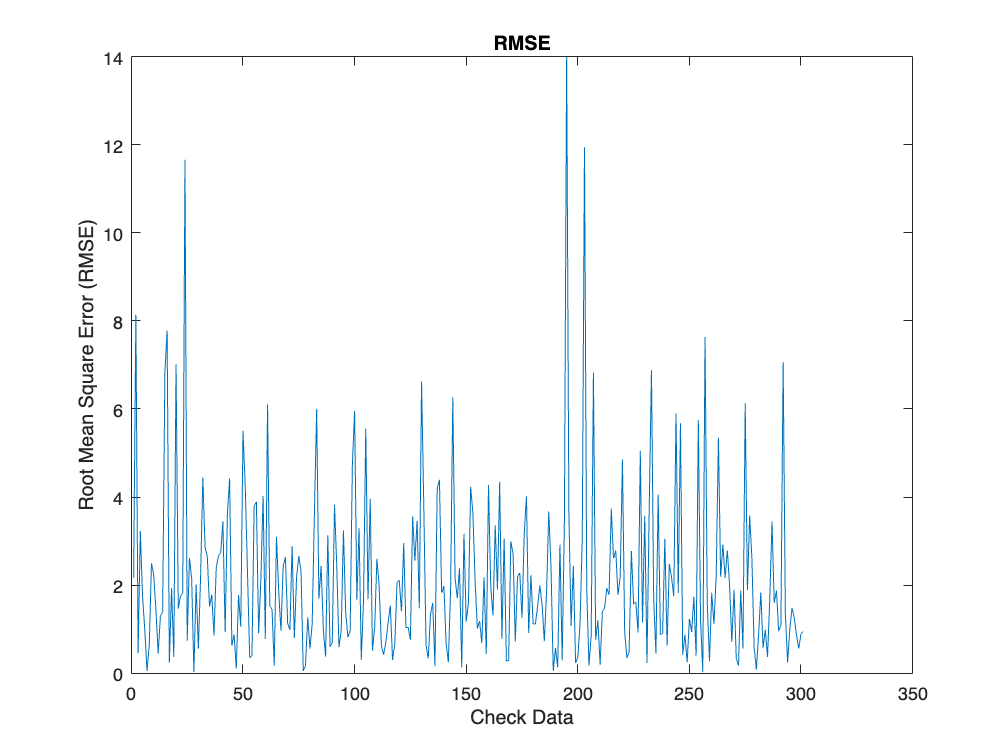

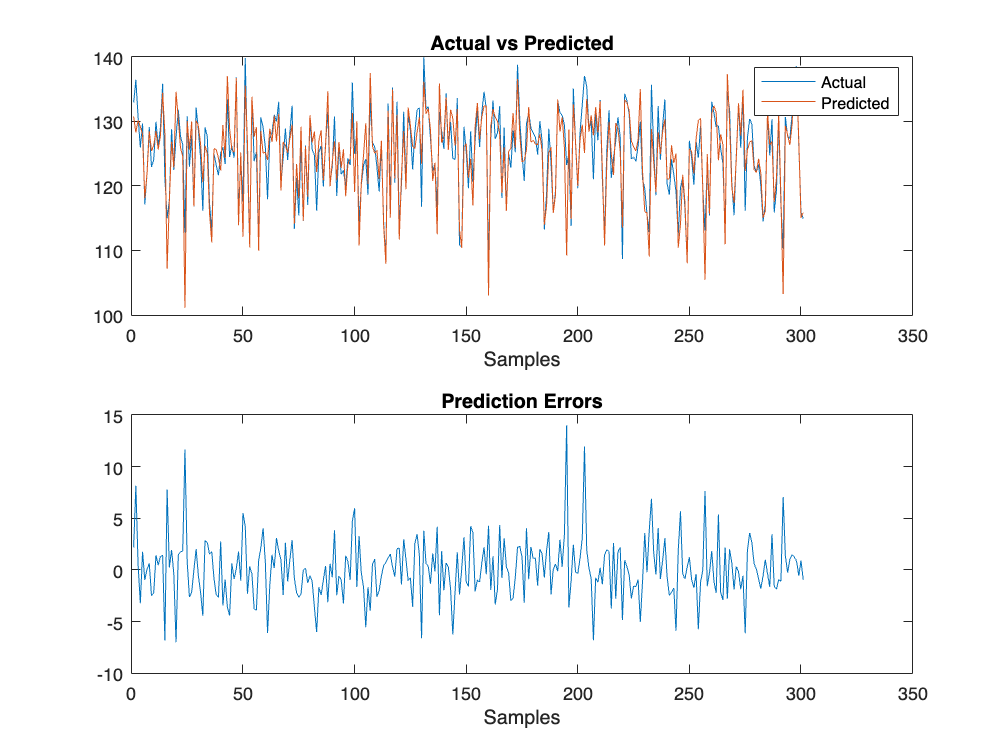

% Evaluate Model 3
[Rmse3, Nmse3, Ndei3, R23] = metrics_evaluation(trained_fis_3, Dchk_1);
plot_metrics(Dchk_1(:, end), evalfis(trained_fis_3, Dchk_1(:, 1:end-1)), training_info_3.trainError, training_info_3.chkError);

model_3_metrics = [Rmse3; Nmse3; Ndei3; R23];
fprintf('Error metrics for TSK model 3:\n RMSE: %.4f, NMSE: %.4f, NDEI: %.4f, R2: %.4f\n', Rmse3, Nmse3, Ndei3, R23);

Error metrics for TSK model 3:
 RMSE: 2.8851, NMSE: 0.1908, NDEI: 0.4368, R2: 0.8092


### TSK Model 4

Finally, the fourth and last model trained for this dataset, is implemented below.

% Define configuration for Model 4
model_4 = struct('Part', '1','NumMFs', 3, 'InputMFT', 'gbellmf', 'OutputMFT', 'linear');

% Initialize Model 4
initial_fis_4 = initialize_tsk_model(Dtrn_1, model_4);
plot_mf(initial_fis_4, 5);

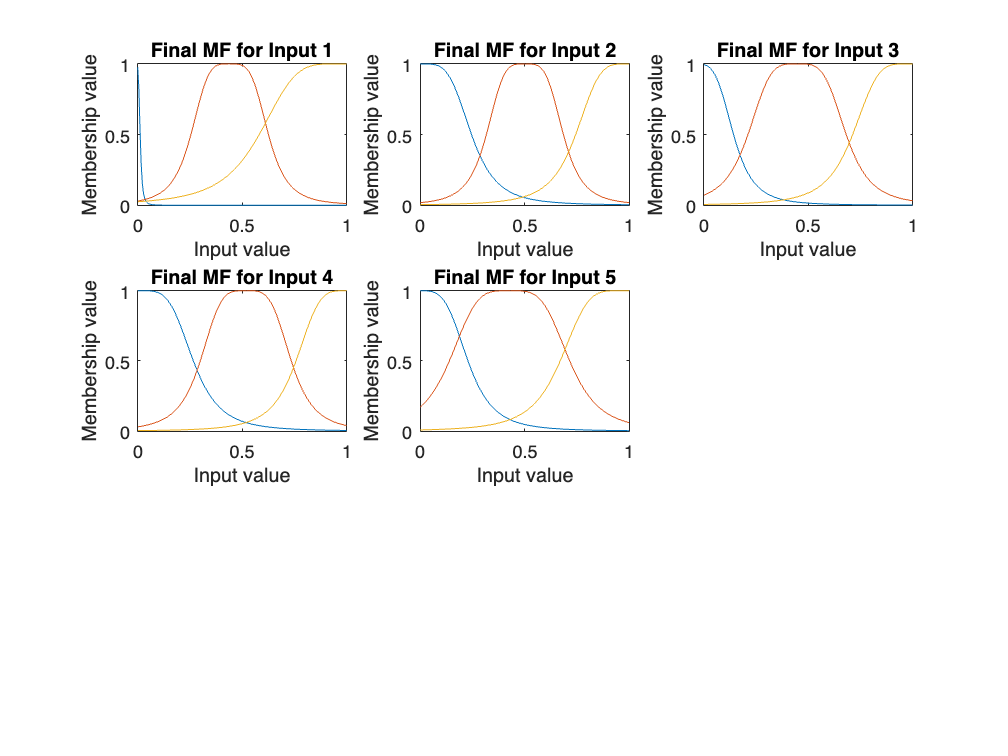

% Train Model 4
tic;
[trained_fis_4, training_info_4] = train_tsk_model(initial_fis_4, Dtrn_1, Dval_1, 100);
time_4 = toc;
plot_mf(trained_fis_4, 5);

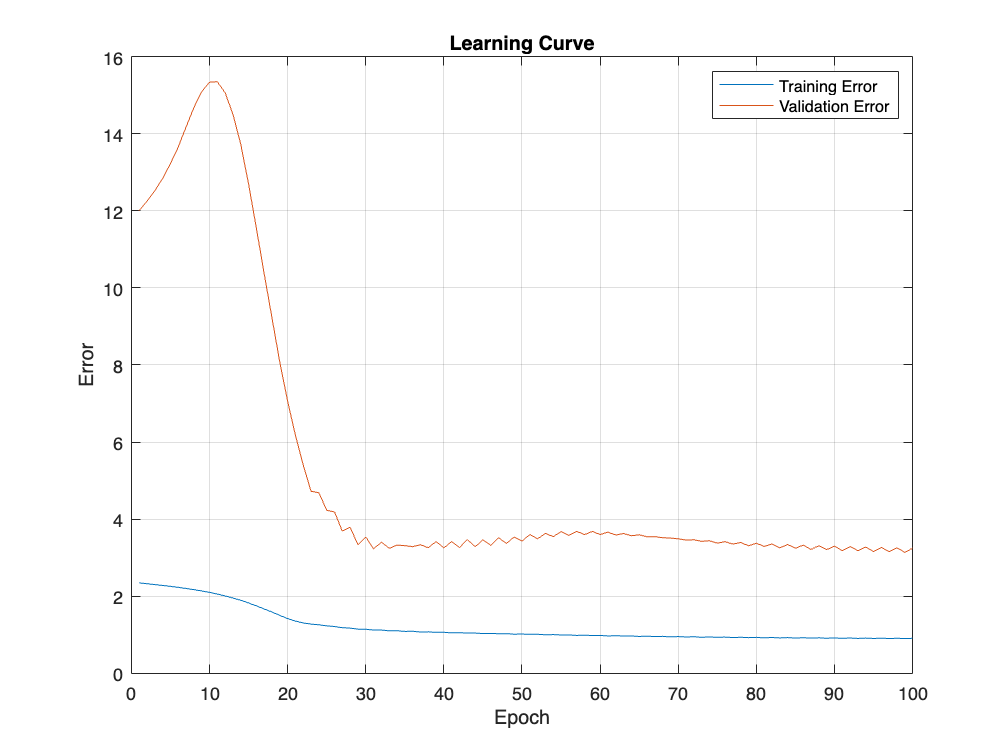

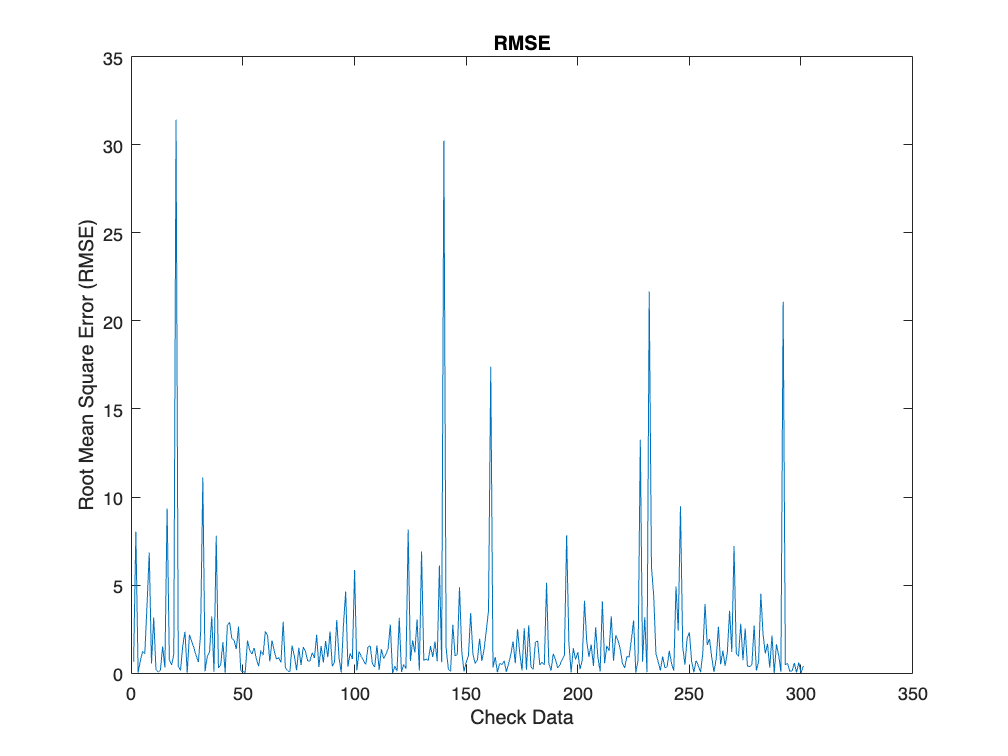

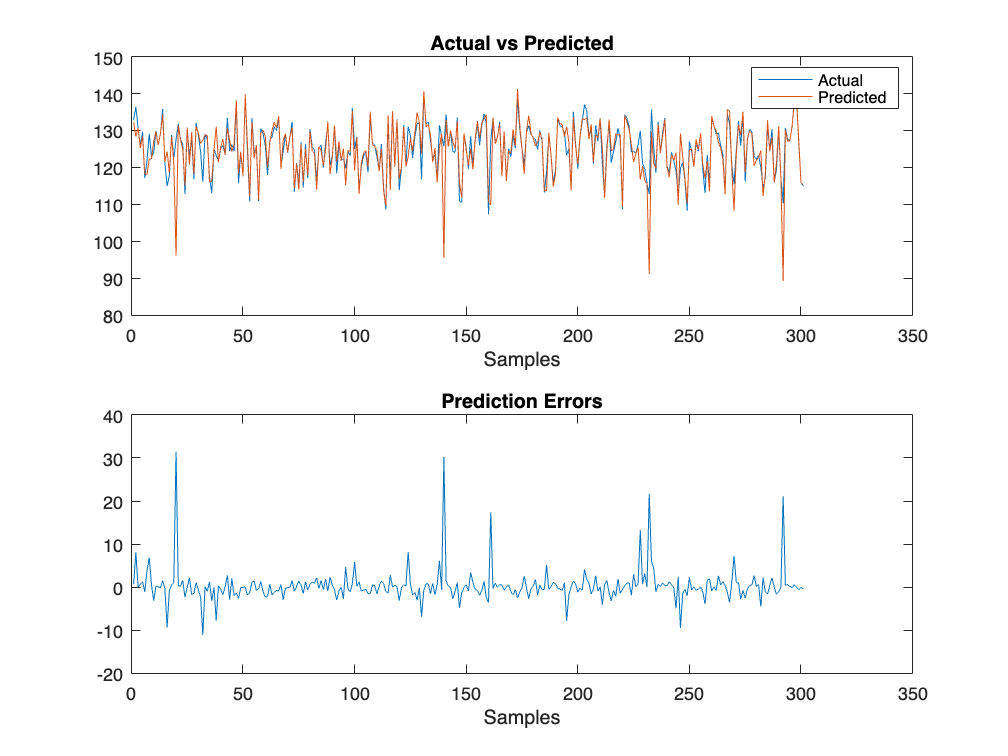

% Evaluate Model 4
[Rmse4, Nmse4, Ndei4, R24] = metrics_evaluation(trained_fis_4, Dchk_1);
plot_metrics(Dchk_1(:, end), evalfis(trained_fis_4, Dchk_1(:, 1:end-1)), training_info_4.trainError, training_info_4.chkError);

model_4_metrics = [Rmse4; Nmse4; Ndei4; R24];
fprintf('Error metrics for TSK model 4:\n RMSE: %.4f, NMSE: %.4f, NDEI: %.4f, R2: %.4f\n', Rmse4, Nmse4, Ndei4, R24);

Error metrics for TSK model 4:
 RMSE: 3.9961, NMSE: 0.3660, NDEI: 0.6050, R2: 0.6340


### Comments and Results

Below we can see the comparison of the 4 models in regard to the evaluating metrics defined previously.

Metrics = {'RMSE'; 'NMSE'; 'NDEI'; 'R2'};
EvalTable = table(Metrics, model_1_metrics, model_2_metrics, model_3_metrics, model_4_metrics);
disp(EvalTable);

    Metrics     model_1_metrics    model_2_metrics    model_3_metrics    model_4_metrics
    ________    _______________    _______________    _______________    _______________

    {'RMSE'}         3.8397             3.5464             2.8851             3.9961    
    {'NMSE'}        0.33789            0.28824            0.19076            0.36598    
    {'NDEI'}        0.58129            0.53688            0.43676            0.60496    
    {'R2'  }        0.66211            0.71176            0.80924            0.63402    



Based on the results above, we can see that the third model, significantly outperforms the rest of the models in every metric. Model 3 incorporates 2 membership functions and a polynomial output. We can see that the output type plays an important role in the model's performance. The singleton output offers more consistent results, whereas the polynomial suggests a correlation with the number of membership functions, since there is a significant divergence in their results between 2 and 3 membership functions.  So considering the above, we can say that between the 4 different combinations, the model 3's provides the best balance between complexity and efficiency.

In all four models, we do not observe conclusive signs of overfitting. Although there is an occasional trend suggesting a potential for overfit, they ultimately diverge toward stabilization of the validation error, indicating that the models generalize well to new data.

Finally, we can see the computational cost in terms of time it took for each model to be trained, below:

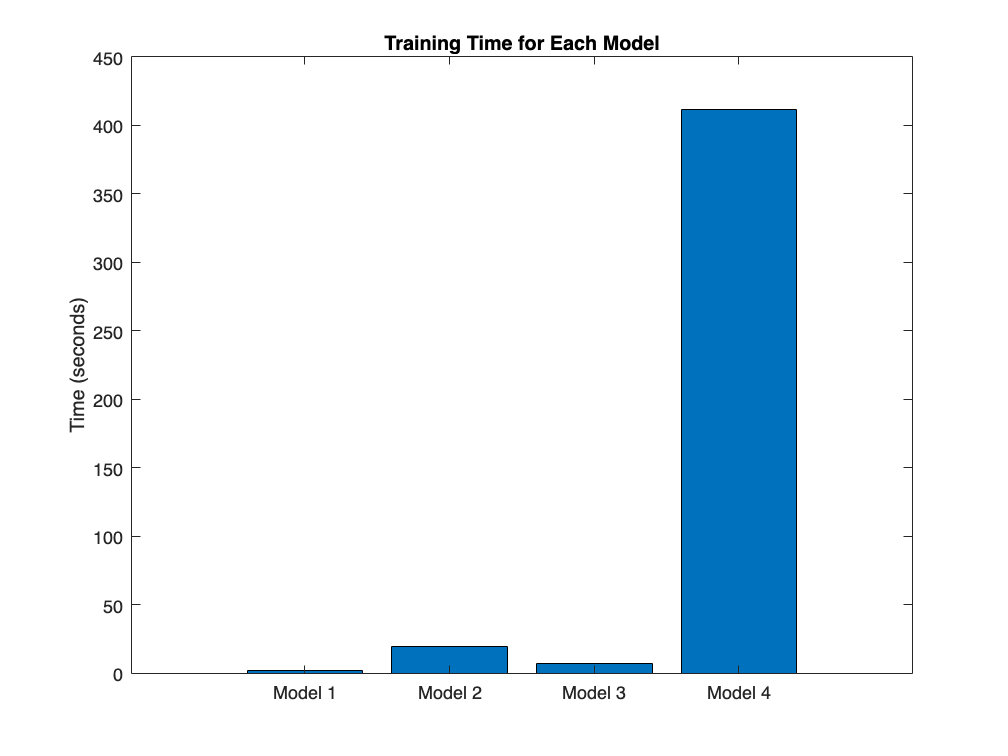

% Create a bar graph for training times
figure;
bar([time_1, time_2, time_3, time_4]);
xticklabels({'Model 1', 'Model 2', 'Model 3', 'Model 4'});
ylabel('Time (seconds)');
title('Training Time for Each Model');

We can clearly see the correlation between the number of membership functions and time complexity. The time difference between model 1 and 2 where their difference is the number of membership functions, is significantly higher than the difference between model 1 and 3 where their difference lies in the output (singleton vs polynomial). When the increased number of membership functions is combined with the polynomial output, which is an additional factor for complexity, we can observe the 'explosion' in complexity. Judging from this metric as well, we can verify the previous statement, that the model 3 strikes the best balance between all the factors.